# Fixed-Point Addition

Whenever you add two fixed-point numbers, you may need a carry bit to correctly represent the result. For this reason, when adding two B-bit numbers (with the same scaling), the resulting value has an extra bit compared to the two operands used.

The addition of fixed-point numbers requires that the binary points of the addends be aligned. The addition is then performed using binary arithmetic so that no number other than 0 or 1 is used.

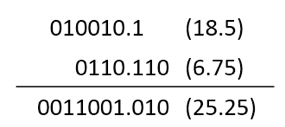

In the following example, note that the sum, $c$, of $a$ and $b$ has a word length (10) equal to one greater than the sum of the largest input fraction length (3), and the largest input integer length ($7-1 = 6$).

a = fi(18.5,0,7,1)

a =   18.500000000000000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 7
        FractionLength: 1

a.bin

ans = '0100101'


b = fi(6.75,0,7,3)

b =    6.750000000000000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 7
        FractionLength: 3

b.bin

ans = '0110110'


c = a + b

c =   25.250000000000000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 10
        FractionLength: 3

c.bin

ans = '0011001010'

## C code generation

codegen myplus -args {a,b} -config:lib -launchreport

Code generation successful: View report



## HDL code generation

codegen myplus -args {a,b} -config:hdl -launchreport


### Begin VHDL Code Generation
### Working on myplus as myplus.vhd.
### Generating Resource Utilization Report resource_report.html.
### Generating HDL Conformance Report myplus_hdl_conformance_report.html.
### HDL Conformance check complete with 0 errors, 0 warnings, and 0 messages.
### Code generation successful: 

## SystemC code generation

cfg = coder.HdlConfig;
cfg.TargetLanguage = "SystemC";
codegen myplus -args {a,b} -config cfg -launchreport


### Begin SystemC Code Generation
### Working on myplusClass.hpp as myplusClass.hpp.
### Working on myplusModule.hpp as myplusModule.hpp.
### Generating HDL Conformance Report myplus_hdl_conformance_report.html.
### HDL Conformance check complete with 0 errors, 0 warnings, and 0 messages.
### Code generation successful: 